clear; % clears memory - useful if you run many scripts in the same session
clf;

%take in data from csv file
tname='BPbode_plot_maybe.csv'; % <-input your data file's name! test2.csv was exported from O-scope software with a line of headers
datatable  = readtable(tname)%makes data table with headers

datatable = 101×3 table
     freq       gain      phase 
    _______    _______    ______

    0.99838    -24.051    141.05
     1.1176    -28.477    133.71
     1.2517    -29.518    128.67
     1.4156    -29.625    126.06
     1.5795    -29.195    122.23
     1.7732    -28.373    119.82
     1.9968    -27.452    115.91
     2.2352    -26.385    112.92
     2.5183    -25.327    109.74
     2.8163    -24.239    107.88
      3.159    -23.222    106.13
     3.5465    -22.212    103.78
     3.9786    -21.142    101.52
     4.4703    -20.128    99.594
     5.0068    -19.073    98.206
     5.6177    -18.062     96.55


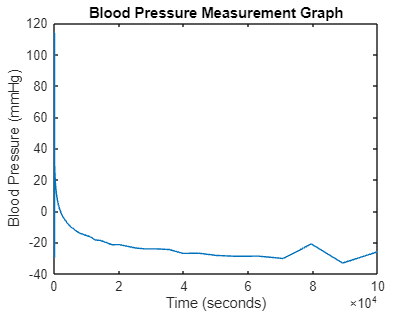


%V1(1:243) = V1(1:243) + 0.35;
%V1(244:end) = V1(244:end) - 1.75;



BP = (((datatable.phase./5) - 0.04) / 0.018) * (760/101.325); %transfer function


%plot (you can change this section to suit your plotting needs!)
%plot(time1(1:400),BP(1:400)) %plots first channel
plot(datatable.freq, datatable.gain)
xlabel('Time (seconds)'); % add x axis label 
%ylim([0 140])
ylabel('Blood Pressure (mmHg)'); % add y axis label 
title('Blood Pressure Measurement Graph');